clc;
close all;
clear variables;

### Simulacija

Parametri simulacije

sim_file_name = "buck_boost_DCDC_sim_3";
open_system(sim_file_name);

sim_duration = 1; % sec
time_step = 1e-4;

Propusni opseg za nelinearne kontrolere

w0 = 125; % rad/s
w_diff = w0 * 20; % da bude dovoljno van propusnog opsega
w_prefiltar = 0.5 * w0; % odokativno

Linearni kontroler

% K_pracenje_ref = kontroler_pracenje_reference_foo();
[K_znf, ~] = ziegler_nichols_frekvencijski_foo();

[Kp, Ti, Td, Tf] = PID_oblik_foo(K_znf);
Tt = 1e-3; % s
[G, ~, ~, ~, ue] = linearizacija();
s = tf('s');
% Kp*2, Ti*1, Td*1.5 
% Kp*2, Ti*0.5, Td*2
Kp = Kp*2

Kp = -0.0121

Ti = Ti*0.5

Ti = 0.0090

Td = Td * 2

Td = 0.0090

Tf = Td / 20;
Kont = Kp *(1 + 1/Ti/s + Td*s/(Tf*s + 1))

Kont =
 
  -0.0001143 s^2 - 0.0127 s - 1.343
  ---------------------------------
           0.00045 s^2 + s
 
Continuous-time transfer function.



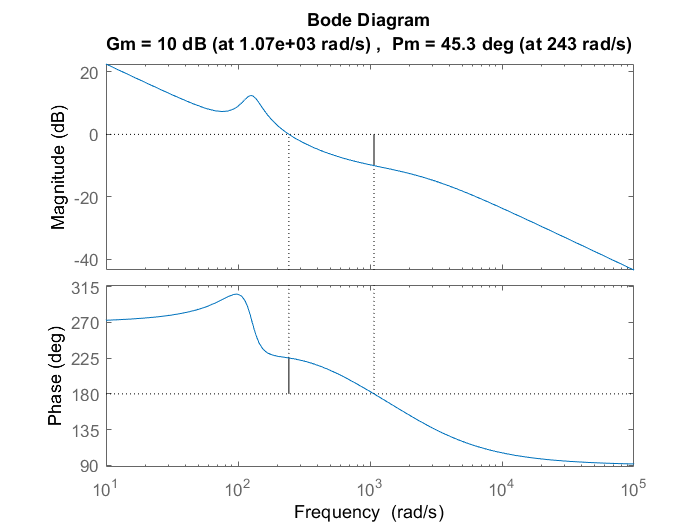

figure()
margin(Kont*G)

Feedback linearizacija

p = 3*w0; %trostruki pol da bi prop opseg bio w0

k_i = p^3;
k_0 = 3*p^2;
k_1 = 3*p;
K_fl = [k_i,k_0,k_1];

subsystem_name = "/Feedback linearizacija";

feedback_linearizacija_foo(sim_file_name, subsystem_name)

Sliding mode control

beta = 10000;
p = 2*w0;
K_0 = 2*p;
K_i = p^2;
K_smc = [K_i, K_0];

K_smc_0 = [0, K_smc];

subsystem_name = "/Klizno upravljanje";
sliding_mode_control_foo(sim_file_name, subsystem_name, K_smc)


Boundry layer sliding mode control

phi = beta / 1 / p; % mora veliko zbog suma
subsystem_name = "/Klizno upravljanje sa granicnim slojem";
sliding_mode_control_foo(sim_file_name, subsystem_name, K_smc)

Parametri sistema

[L, R, C, E, x_2e] = nominalni_parametri();

Referenca i poremecaj

t_ref = [1/6, 2/6, 3/6, 4/6 ] * sim_duration;
step_ref = [0.5, -0.5, -0.5, 0.5] * x_2e;

t_poremecaj = [5/6] * sim_duration;
step_poremecaj = [1/3] * E;

Opsti parametri kontrolera

R_dot_enable = 0;
prefiltar_enable = 1;
noise_enable = 0;

sigma_noise = 0.02 * abs(x_2e);


% "smc", "fbl", "bl smc", "lin", "fuzzy"
ime_kontrolera = "lin";

if ime_kontrolera == "lin" || true
    step_ref = [0.05, -0.05, -0.05, 0.05] * x_2e;
    step_poremecaj = [1/6] * E;
end

Simulacija

out = sim(sim_file_name);

### Crtanje

main_plot_linewidth = 1;
auxiliary_plot_linewidth = 0.5;
fig_vector = [10, 10, 700, 350];

#### Upravljanje

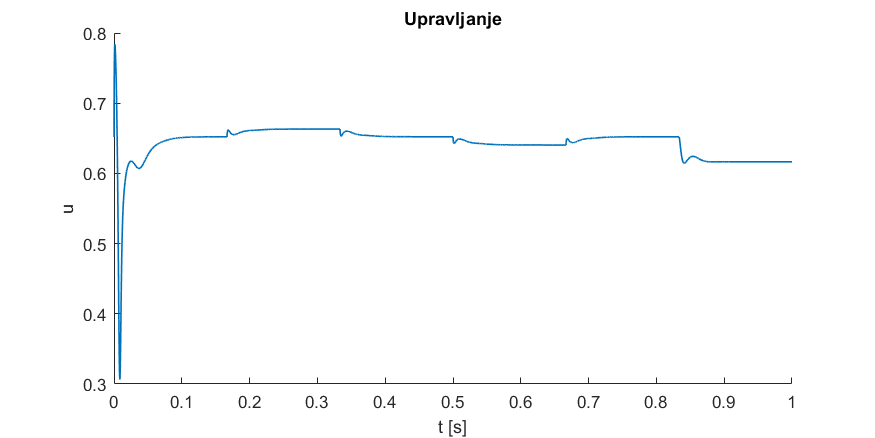

y_oznaka = "u";
naslov = "Upravljanje";
target_timeseries = out.upravljanje;
ref_flg = false;
poremecaj_flg = false;

fig = figure();
set(gcf,'Position', fig_vector)

fig = crtanje_celog_signala(fig, naslov, y_oznaka, target_timeseries, t_ref, t_poremecaj, main_plot_linewidth, auxiliary_plot_linewidth, ref_flg, poremecaj_flg);

Prelazak ka nominalnom rezimu rada

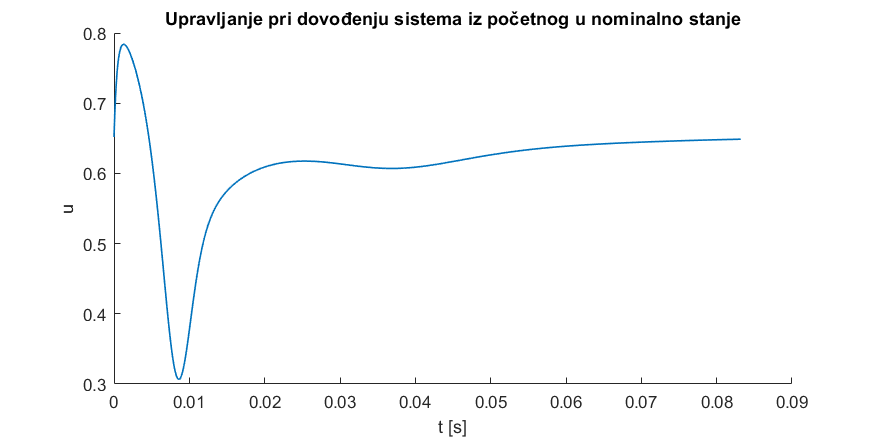

naslov = "Upravljanje pri dovođenju sistema iz početnog u nominalno stanje";
t_start = 0;
t_end = 0.5 * t_ref(1);

fig = figure();
set(gcf,'Position', fig_vector)

plt = crtanje_segmenta_vremena(fig, naslov, y_oznaka, out, target_timeseries, t_start, t_end, main_plot_linewidth);

Odziv na referencu

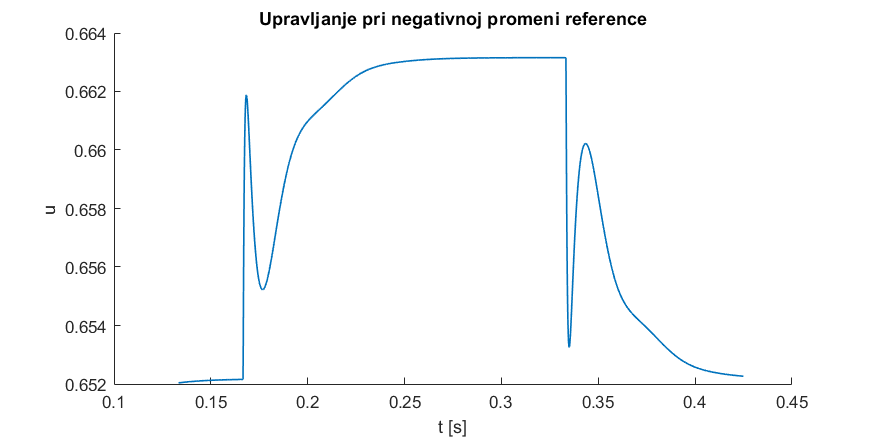

naslov = "Upravljanje pri negativnoj promeni reference";
t_start = 0.8 * t_ref(1);
t_end = 0.85 * t_ref(3);

fig = figure();
set(gcf,'Position', fig_vector)

plt = crtanje_segmenta_vremena(fig, naslov, y_oznaka, out, target_timeseries, t_start, t_end, main_plot_linewidth);

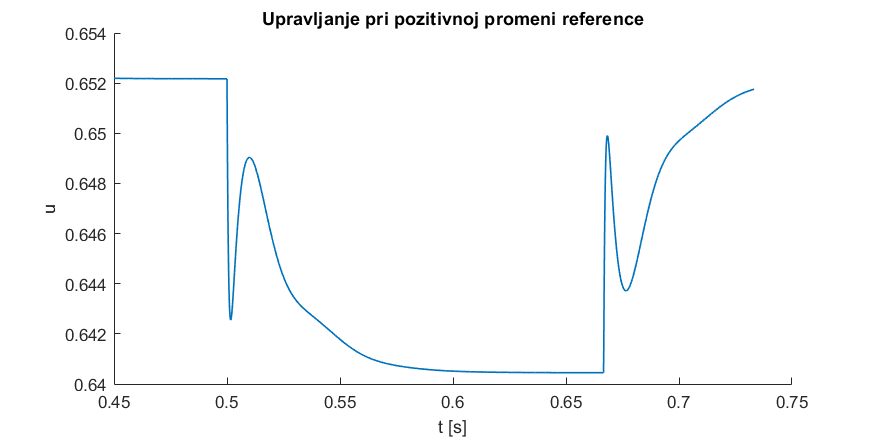

naslov = "Upravljanje pri pozitivnoj promeni reference";

t_start = 0.9 * t_ref(3);
t_end = 1.1 * t_ref(4);

fig = figure();
set(gcf,'Position', fig_vector)

plt = crtanje_segmenta_vremena(fig, naslov, y_oznaka, out, target_timeseries, t_start, t_end, main_plot_linewidth);

Poremecaj

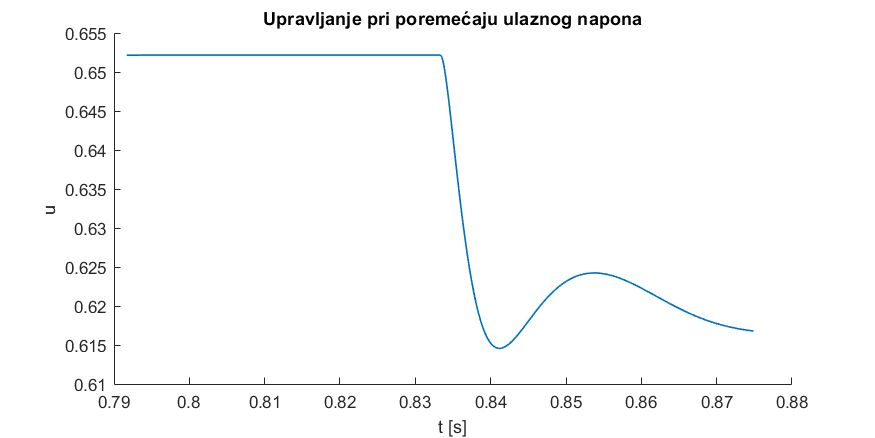

naslov = "Upravljanje pri poremećaju ulaznog napona";
t_start = 0.95 * t_poremecaj(1);
t_end = 1.05 * t_poremecaj(1);

fig = figure();
set(gcf,'Position', fig_vector)

plt = crtanje_segmenta_vremena(fig, naslov, y_oznaka, out, target_timeseries, t_start, t_end, main_plot_linewidth);

#### Izlaz

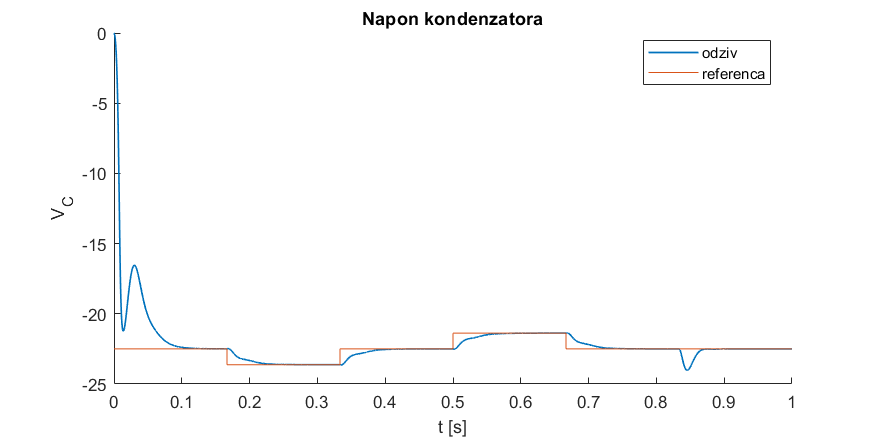

y_oznaka = "V_C";
naslov = "Napon kondenzatora";
target_timeseries = out.x2;
ref_flg = false;
poremecaj_flg = false;

fig = figure();
set(gcf,'Position', fig_vector)

fig = crtanje_celog_signala(fig, naslov, y_oznaka, target_timeseries, t_ref, t_poremecaj, main_plot_linewidth, auxiliary_plot_linewidth, ref_flg, poremecaj_flg);
fig = crtanje_reference(fig, out, 0, sim_duration);

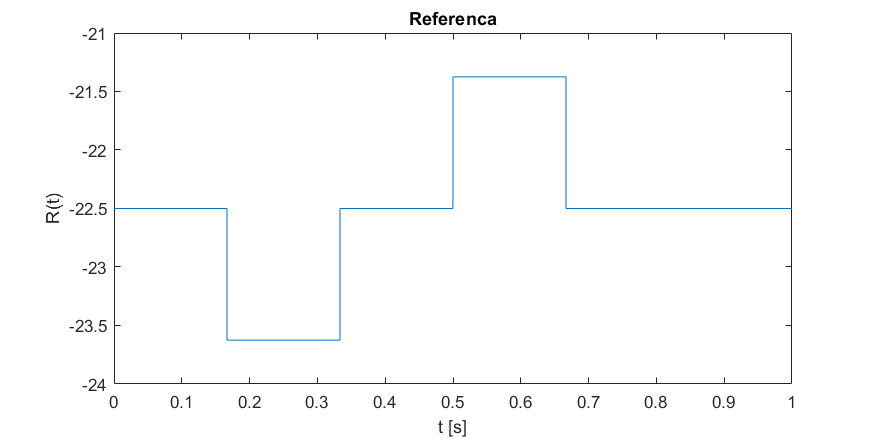


fig = figure();

set(gcf,'Position', fig_vector)
plot(out.ref_no_filter)

title("Referenca")
xlabel("t [s]")
ylabel("R(t)")

Prelazak ka nominalnom rezimu rada

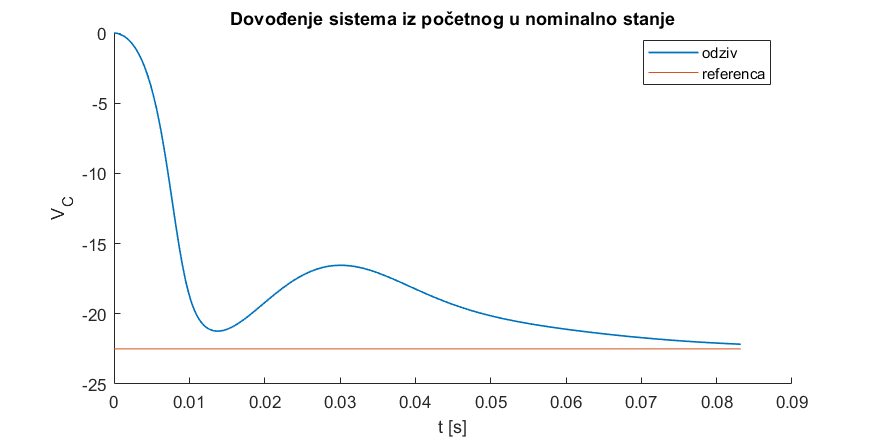

naslov = "Dovođenje sistema iz početnog u nominalno stanje";
t_start = 0;
t_end = 0.5 * t_ref(1);

fig = figure();
set(gcf,'Position', fig_vector)

plt = crtanje_segmenta_vremena(fig, naslov, y_oznaka, out, target_timeseries, t_start, t_end, main_plot_linewidth);

fig = crtanje_reference(fig, out, t_start, t_end);

Odziv na referencu

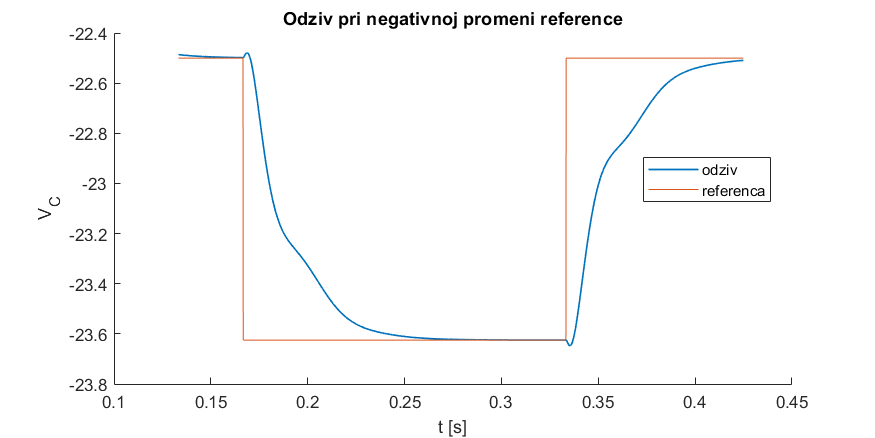

naslov = "Odziv pri negativnoj promeni reference";
t_start = 0.8 * t_ref(1);
t_end = 0.85 * t_ref(3);

fig = figure();
set(gcf,'Position', fig_vector)

plt = crtanje_segmenta_vremena(fig, naslov, y_oznaka, out, target_timeseries, t_start, t_end, main_plot_linewidth);
fig = crtanje_reference(fig, out, t_start, t_end);

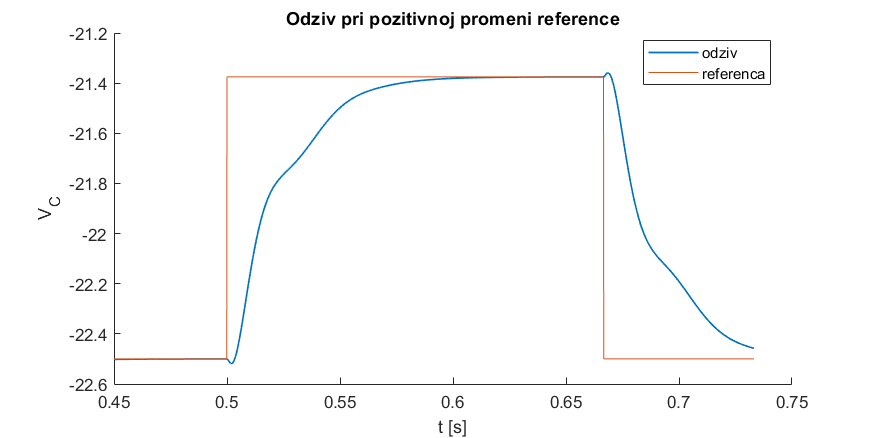

naslov = "Odziv pri pozitivnoj promeni reference";
t_start = 0.9 * t_ref(3);
t_end = 1.1 * t_ref(4);

fig = figure();
set(gcf,'Position', fig_vector)

plt = crtanje_segmenta_vremena(fig, naslov, y_oznaka, out, target_timeseries, t_start, t_end, main_plot_linewidth);
fig = crtanje_reference(fig, out, t_start, t_end);

Poremecaj

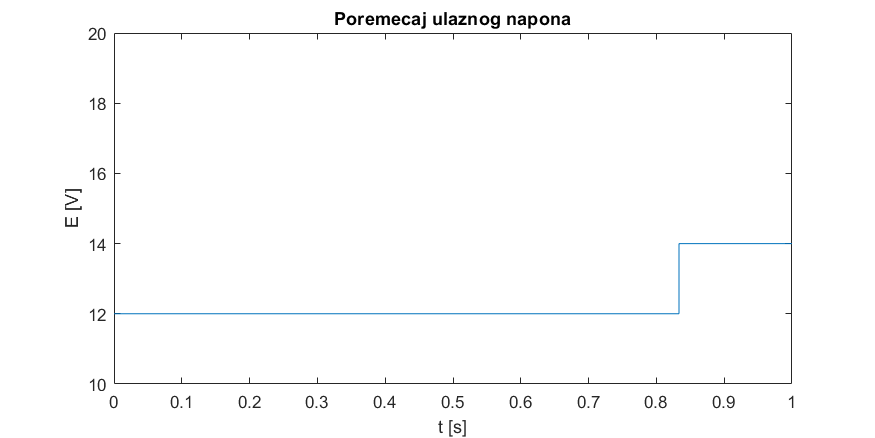


t_start = 0;

t_end = sim_duration;


fig = figure();
set(gcf,'Position', fig_vector)

plt = plot(out.poremecaj + E);
title("Poremecaj ulaznog napona")
xlabel("t [s]")
ylabel("E [V]")
ylim([10, 20])
xlim([t_start, t_end])

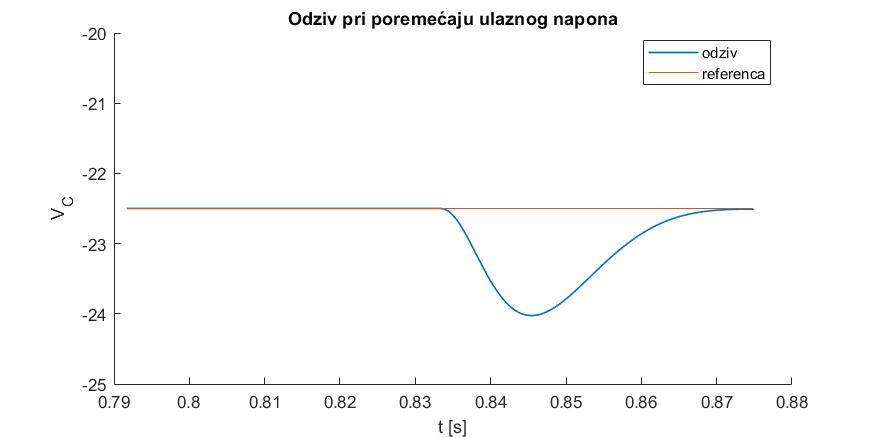

t_start = 0.95 * t_poremecaj(1);
t_end = 1.05 * t_poremecaj(1);

naslov = "Odziv pri poremećaju ulaznog napona";

fig = figure();
set(gcf,'Position', fig_vector)

plt = crtanje_segmenta_vremena(fig, naslov, y_oznaka, out, target_timeseries, t_start, t_end, main_plot_linewidth);
fig = crtanje_reference(fig, out, t_start, t_end);
ylim([-25, -20])

#### Fazni portret

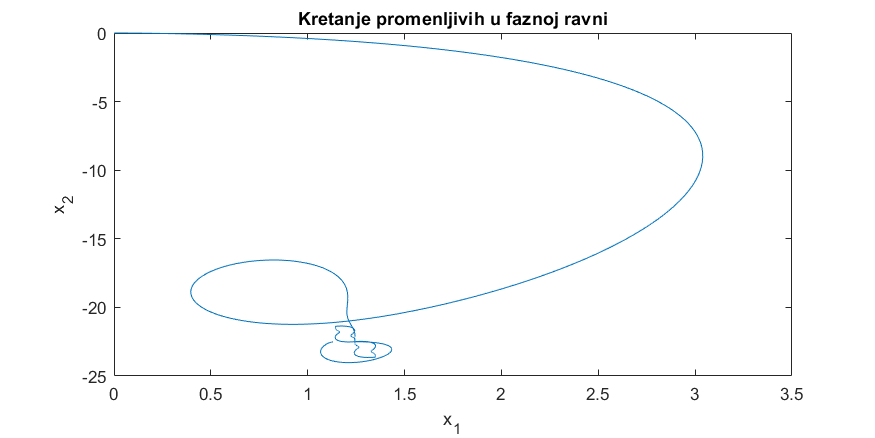

fig = figure();
set(gcf,'Position', fig_vector)

plot(out.x1.Data, out.x2.Data)
title("Kretanje promenljivih u faznoj ravni")
xlabel("x_1")
ylabel("x_2")